# CNT iEEG Pre-processing Pipeline

This notebook provides a recommended usage pipeline for the iEEG pre-processing toolkit.

## Set Paths

The work path should be the path to the 'matlab' toolkit folder.

%set path
work_path = "/Users/meow/Documents/GitHub/CNT_research_tools/matlab";

% Add path to this codebase
addpath(genpath(work_path))
runtests('test/dependTest'); % ensure dependencies exist

Running dependTest
.
Done dependTest
__________



%max_disp = 5; % need fix depending on different file
 

## Login Configuration

An iEEG.org login account is required for obtaining data.

runtests('test/authTest');

Running authTest
.
Done authTest
__________



config_path = strcat(work_path,filesep,'config.json');
login = read_json(config_path);
 

For first time users, please set up config.json file and password .bin file before run

Suggested syntax:

username = 'abcd';
password = 'abcdedf';
path = IEEGSession.createPwdFile(username, password);

-- -- IEEG password file saved -- --


Then save the password file in the *matlab* folder with name 'usr_ieeglogin.bin'.

Update config.json file to specify username and password file name.

config_path = strcat(work_path,filesep,'config.json');
data = read_json(config_path);
data.usr = username;
data.pwd = strcat(username(1:3),'_ieeglogin.bin');
json_str = jsonencode(data);
fid = fopen(config_path, 'w');
fprintf(fid, json_str);
fclose(fid);
 

## Demo of functions

Showcase of usage and recommended order of functions.

### Get Data via Input

- **File name:** the name of target file at ieeg.org

- **Start time: **the start time of target clip in seconds 

- **Stop time: **the stop time of target clip in seconds 

- **Include electrodes (optional): **manually define a set of electrodes to be included in analysis

- **Exclude electrodes (optional): **manually define a set of electrodes to be excluded in analysis

file_name = 'HUP172_phaseII';
start = 402580;
stop = 402600;
selecElecs = strsplit('',', ','CollapseDelimiters',false);
ignoreElecs = strsplit('',', ','CollapseDelimiters',false);
assert(~isempty(file_name),'CNTtools:invalidInput','No test case to run.');
times = [start stop];
if isempty(selecElecs{1})
    selecElecs = {};
end
if isempty(ignoreElecs{1})
    ignoreElecs = {};
end

### Download data

Download data from ieeg.org.

Suggested syntax:

data = get_ieeg_data(file_name, login.usr, login.pwd, times, ...
    'selecElecs',selecElecs,'ignoreElecs',ignoreElecs);

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
02:39:14,068 ERROR edu.upenn.cis.db.mefview.services.TimeSeriesInterface:770 - caught exception
edu.upenn.cis.db.mefview.services.IeegWsRemoteException: An error response with status 500 (Internal Server Error) was returned from the server
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.responseToException(IeegWsErrorHandler.java:88)
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.handleErrorClientResponse(IeegWsErrorHandler.java:45)
	at edu.upenn.cis.db.mefview.services.TimeSeriesInterface.getUnscaledTimeSeriesSetRaw(TimeSeriesInterface.java:619)


### Identifiy Non-iEEG channels

Find and return a boolean mask for Non-iEEG channels, 0 = iEEG, 1 = Non-iEEG

Suggested syntax:

%% Non intracranial
data.nonieeg = find_non_ieeg(data.chLabels);
% for test
extra_cranial_table = cell2table(data.chLabels(data.nonieeg),"VariableNames",["Non-intracranial Channels"])

extra_cranial_table = 2×1 table
    Non-intracranial Channels
    _________________________

            {'EKG1'}         
            {'EKG2'}         


### Identifiy Bad Channels

Find and return a boolean mask for bad channels (1 = bad channels), and details for reasons to reject.

Suggested syntax:

%% Identify bad channels
[data.bad, details] = identify_bad_chs(data.values,data.fs);

% for test
bad_table = cell2table(data.chLabels(data.bad),"VariableNames",["Bad Channels"])

bad_table = 4×1 table
    Bad Channels
    ____________

      {'LB12'}  
      {'RE8' }  
      {'RE9' }  
      {'RE10'}  


disp('Specific reasons for being rejected:')

Specific reasons for being rejected:


for i = fieldnames(details)'
    disp(strcat([i{1},': ',strjoin(data.chLabels(eval(strcat(['details.',i{1}]))'))]));
end

noisy: LB12 RE8 RE9 RE10
nans:
zeros:
var:
higher_std:
high_voltage:


### Clean Data

Remove Non-iEEG and bad channels from data

data.clean_data = data.values(:,~data.nonieeg&~data.bad);
data.clean_chs = data.chLabels(~data.nonieeg&~data.bad);

### Filtering

Filter iEEG signal with bandpass and notch filter.

Suggested syntax:

low_freq, high_freq, notch_freq (optional).

low_freq = 1;
high_freq = 120;
notch_freq = 60;
data.filtered = bandpass_filter(data.clean_data,data.fs,low_freq,high_freq);
filtered_data =  notch_filter(data.filtered,data.fs,notch_freq);
 

### Re-referencing

Re-reference data to a different montage

Available options:

- Common Average Re-referencing (CAR)

- Bipolar Re-referencing (BR)

- Laplacian Re-referencing (LAR): Note, requires location of electrodes and radius threshold

Suggested syntax:

which_reference = 'bipolar';
refMap = containers.Map({'car','bipolar','laplacian'}, {@car, ...
                                        @bipolar, ...
                                        @laplacian});
func = refMap(which_reference);
[data.ref,data.ref_chLabels] = func(data.filtered,data.clean_chs);
 

### Prewhitening (optional)

Suggested syntax:

data.prewhite = pre_whiten(data.ref);
 

### Plot Data

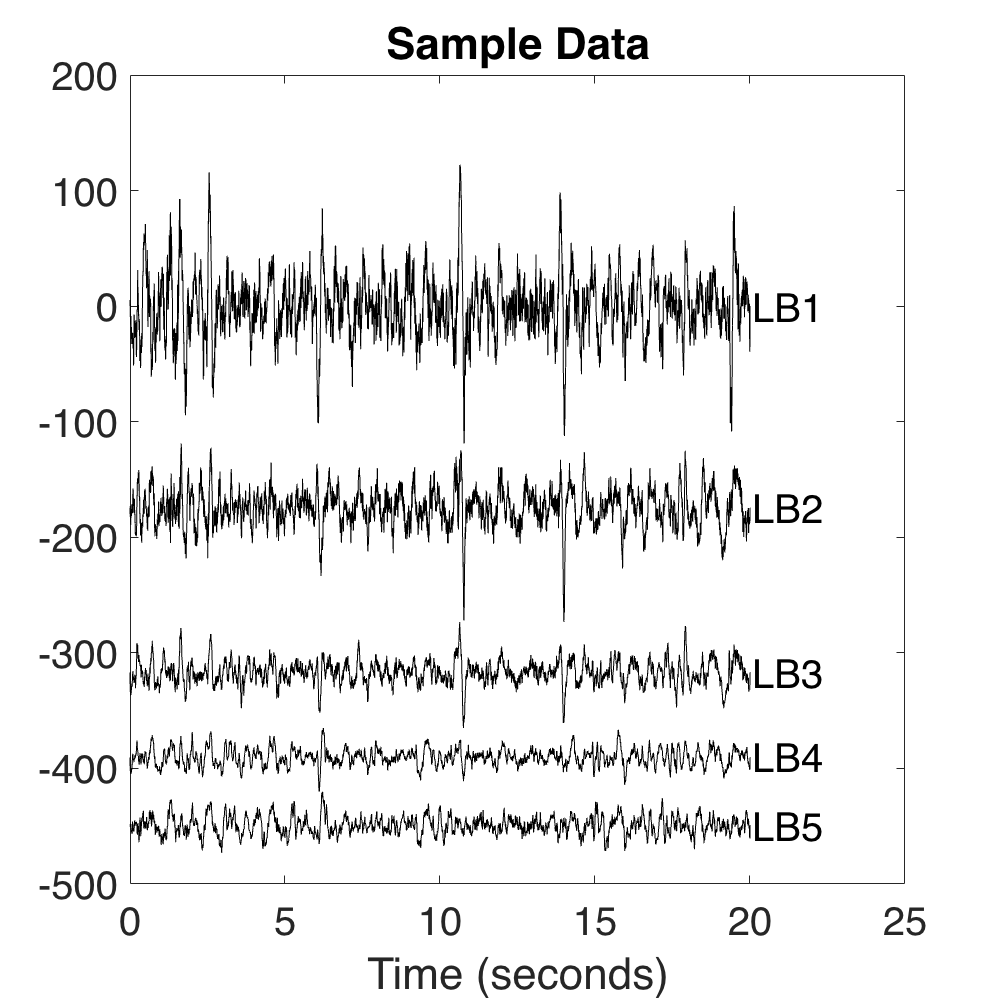

show_eeg(data.ref,data.fs,data.clean_chs,5);
set(gcf,'position',[0,0,500,500])
title('Sample Data')

## Batch Processing

### Get Data via File

**File upload:** Input file should be of .csv/.tsv format, with columns labeled as:

- **filename**: *string*, the name of target file at ieeg.org

- **start: ***numeric*, the start time of target clip in seconds 

- **stop: ***numeric*, the stop time of target clip in seconds 

- **selecElecs: ***string*, electrodes to be included in analysis, separated by ', '

- **ignoreElecs: ***string*, electrodes to be excluded in analysis, separated by ', '

filePath = 'pipeline_testInput.csv';
assert(~isempty(filePath),'CNTtools:invalidInput','No test case to run.');
assert(exist(filePath,'file')==2,'CNTtools:dependencyUnavailable','Specified file not exist.')
param = table2struct(readtable(filePath,'Format','auto'));
 

### Settings

low_freq = 1;
high_freq = 120;
notch_freq = 60;
which_reference = 'bipolar';
refMap = containers.Map({'car','bipolar','laplacian'}, {@car, ...
                                        @bipolar, ...
                                        @laplacian});
func = refMap(which_reference);

If save output data files:

ifsave = true;
save_path = 'data';
if exist(save_path,'dir')~=2
    mkdir(save_path);
end

addpath(genpath(save_path));
 
for i = 1:length(param)
    file_name = param(i).filename;
    start = param(i).start;
    stop = param(i).stop;
    if isnan(param(i).selecElecs)
        selecElecs = {};
    else
        selecElecs = strsplit(param(i).selecElecs,', ','CollapseDelimiters',false);
    end
    if isnan(param(i).ignoreElecs)
        ignoreElecs = {};
    else
        ignoreElecs = strsplit(param(i).ignoreElecs,', ','CollapseDelimiters',false);
    end
    times = [start stop];
    data = get_ieeg_data(file_name, login.usr, login.pwd, times,'selecElecs',selecElecs,'ignoreElecs',ignoreElecs);
    data.nonieeg = find_non_ieeg(data.chLabels);
    [data.bad, details] = identify_bad_chs(data.values,data.fs);
    data.clean_data = data.values(:,~data.nonieeg&~data.bad);
    data.clean_chs = data.chLabels(~data.nonieeg&~data.bad);
    data.filtered = bandpass_filter(data.clean_data,data.fs,low_freq,high_freq);
    data.filtered =  notch_filter(data.filtered,data.fs,notch_freq);
    [data.ref,data.ref_chLabels] = func(data.filtered,data.clean_chs);
    if ifsave
        save(strcat([save_path,filesep,file_name,'_',num2str(start),'_', ...
            num2str(stop),'.mat']),'data');
    end
    dataFull(i) = data;
end

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
05:39:09,794 ERROR edu.upenn.cis.db.mefview.services.TimeSeriesInterface:770 - caught exception
edu.upenn.cis.db.mefview.services.IeegWsRemoteException: An error response with status 500 (Internal Server Error) was returned from the server
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.responseToException(IeegWsErrorHandler.java:88)
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.handleErrorClientResponse(IeegWsErrorHandler.java:45)
	at edu.upenn.cis.db.mefview.services.TimeSeriesInterface.getUnscaledTimeSeriesSetRaw(TimeSeriesInterface.java:619)
IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Fo

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****
05:39:30,547 ERROR edu.upenn.cis.db.mefview.services.TimeSeriesInterface:770 - caught exception
edu.upenn.cis.db.mefview.services.IeegWsRemoteAppException: The server responded with 500 Internal Server Error. If reporting the error please include the following: Error code: [InternalError], Error message: [An error occured on the server], host: [ip-10-0-0-27.ec2.internal], error id: [76282a6d-8f06-4357-b64b-91793dcc66e7].
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.responseToException(IeegWsErrorHandler.java:73)
	at edu.upenn.cis.db.mefview.services.IeegWsErrorHandler.handleErrorClientResponse(IeegWsErrorHandler.java:45)
	at edu.upenn.cis.db.mefview.services.TimeSeriesInterface.getUnscaledTimeSeriesSetRaw(TimeSeriesInterface.java:619)
